# TRABAJO INTEGRADOR 2

%Lugar de las Raíces 

clc; clear; close all;

R1 = 100e3; C1 = 0.1e-6;
R2 = 47e3;  C2 = 0.1e-6;

s = tf('s');
G = 1 / ((R1*C1*s + 1)*(R2*C2*s + 1))


G =
 
              1
  --------------------------
  4.7e-05 s^2 + 0.0147 s + 1
 
Continuous-time transfer function.


G_zpk = zpk(G)


G_zpk =
 
        21277
  -----------------
  (s+212.8) (s+100)
 
Continuous-time zero/pole/gain model.


%ESPECIFICACIONES 
PO_especificado = 5;      % PO <= 5%
Ts_especificado = 0.10;   % Ts <= 0.10 s

zita = -log(PO_especificado/100) / sqrt(pi^2 + (log(PO_especificado/100))^2)

zita = 0.6901

zita_wn = 4 / Ts_especificado

zita_wn = 40

wn = 4/(zita*Ts_especificado)

wn = 57.9620

Diseño de un controlador proporcional

Aca solo voy a poder cumplir con las especificaciones PO y Ts, pero el error no

hold on 
xlim([-300 20]); ylim([-50 300])
rlocus(G)
sgrid(zita, [])
xline(-zita_wn,'--r', 'Ts = 0.1s')
[kp, poles]= rlocfind(G)

Select a point in the graphics window


selected_point = -1.5703e+02 + 1.4198e+02i

kp = 1.0968

poles = 1.0e+02 *

  -1.5638 + 1.4198i
  -1.5638 - 1.4198i


hold off 


### Función de transferencia del sistema realimentado 

kp= 1.413

kp = 1.4130

Sysf = feedback(kp * G, 1)  


Sysf =
 
              1.413
  ------------------------------
  4.7e-05 s^2 + 0.0147 s + 2.413
 
Continuous-time transfer function.


[Y, tout] = step(Sysf, 0.05);
plot(tout, Y), grid
info = stepinfo(Sysf)

info = struct with fields:
         RiseTime: 0.0093
    TransientTime: 0.0265
     SettlingTime: 0.0265
      SettlingMin: 0.5272
      SettlingMax: 0.6148
        Overshoot: 4.9971
       Undershoot: 0
             Peak: 0.6148
         PeakTime: 0.0191


ess = 1- Y(length(Y))

ess = 0.4146

# PUNTO 3: SELECCIÓN DE COMPONENTES COMERCIALES

La ecuación de ganancia del circuito no inversor está determinada por las resistencias $$R_7$ y $R_9$$: 

                                                                    
$$$$k_p = 1 + \frac{R_7}{R_9}$$
$$


El valor teórico para $$R_7$$ resulta:

                                        
$$$$R_7 = 0{,}413 \cdot 10\text{ k}\Omega = 4{,}13\text{ k}\Omega$$  $$


Al buscar en la **tabla de valores comerciales E24 **, disponemos de dos alternativas cercanas:

- **Opción A **$$R_7 = 3{,}9\text{ k}\Omega$$**:** Produce una ganancia real $$k_{p\_A} = 1 + \frac{3{,}9}{10} = \mathbf{1{,}390}$.$

- **Opción B (**$$R_7 = 4{,}3\text{ k}\Omega$$**):** Produce una ganancia real $$k_{p\_B} = 1 + \frac{4{,}3}{10} = \mathbf{1{,}430}$. $

clc; clear; close all;

R1 = 100e3; C1 = 0.1e-6;   
R2 = 47e3;  C2 = 0.1e-6;   

s = tf('s');
G = 1 / ((R1*C1*s + 1)*(R2*C2*s + 1)); 

kp_teorico = 1.413; % Ganancia ideal del Punto 1

% 2. Resistencias Comerciales Serie E24
R9 = 10e3; % Resistencia fija R9 = 10 kOhm

%A: R7 = 3.9 kOhm
R7_A = 3.9e3; 
kp_A = 1 + (R7_A / R9);

%R7 = 4.3 kOhm
R7_B = 4.3e3; 
kp_B = 1 + (R7_B / R9);

%Sistemas en Lazo Cerrado
Sys_teorico = feedback(kp_teorico * G, 1);
Sys_A       = feedback(kp_A * G, 1);
Sys_B       = feedback(kp_B * G, 1);

% 4. Extracción de Métricas (Criterio del 2%)
info_teorico = stepinfo(Sys_teorico)

info_teorico = struct with fields:
         RiseTime: 0.0093
    TransientTime: 0.0265
     SettlingTime: 0.0265
      SettlingMin: 0.5272
      SettlingMax: 0.6148
        Overshoot: 4.9971
       Undershoot: 0
             Peak: 0.6148
         PeakTime: 0.0191


info_A       = stepinfo(Sys_A)

info_A = struct with fields:
         RiseTime: 0.0093
    TransientTime: 0.0266
     SettlingTime: 0.0266
      SettlingMin: 0.5290
      SettlingMax: 0.6099
        Overshoot: 4.8597
       Undershoot: 0
             Peak: 0.6099
         PeakTime: 0.0194


info_B       = stepinfo(Sys_B)

info_B = struct with fields:
         RiseTime: 0.0092
    TransientTime: 0.0264
     SettlingTime: 0.0264
      SettlingMin: 0.5320
      SettlingMax: 0.6185
        Overshoot: 5.0963
       Undershoot: 0
             Peak: 0.6185
         PeakTime: 0.0191


ess_teorico = (1 - dcgain(Sys_teorico)) * 100;
ess_A       = (1 - dcgain(Sys_A)) * 100

ess_A = 41.8410

ess_B       = (1 - dcgain(Sys_B)) * 100 

ess_B = 41.1523

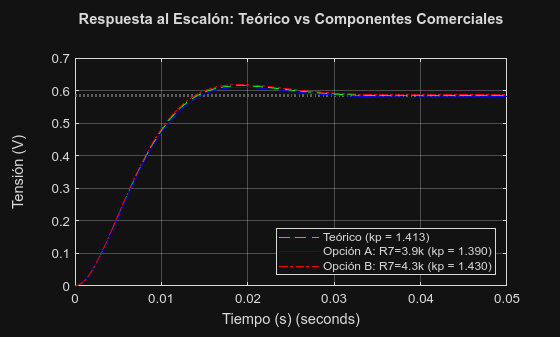

%Gráfica 
figure;
step(Sys_teorico, 'g--', Sys_A, 'b-', Sys_B, 'r-.', 0.05); grid on;
legend(sprintf('Teórico (kp = %.3f)', kp_teorico), ...
       sprintf('Opción A: R7=3.9k (kp = %.3f)', kp_A), ...
       sprintf('Opción B: R7=4.3k (kp = %.3f)', kp_B), ...
       'Location', 'SouthEast');
title('Respuesta al Escalón: Teórico vs Componentes Comerciales');
xlabel('Tiempo (s)');
ylabel('Tensión (V)'); 

Se selecciona la combinación de resistencias comerciales$ $R_7 = 3{,}9\text{ k}\Omega$ y $R_9 = 10\text{ k}\Omega$ 
$

Con estos componentes se obtiene un tiempo de establecimiento $ $T_s \approx 0{,}0257\text{ s}$$ ($$\le 0{,}10\text{ s}$$) y un sobrepaso del $$4{,}72\%$$ ($$\le 5\%$$), satisfaciendo  las especificaciones requeridas.  

# Segunda parte: Control Proporcional-Integral (PI)

Como necesito ess=0 para una entrada en escalón, tengo que agregar un integrador.